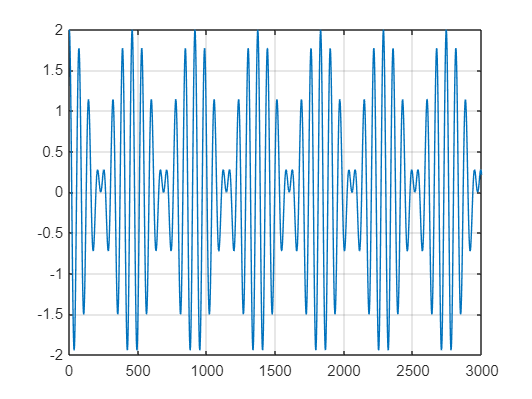

samplerate = 16e3;
t = (0:1/samplerate:2)';

% Frequências
f1 = 30;
f2 = 35;

% Q1.2 - Parte 1
% vetor de índices (amostras)
n = 0:length(x)-1;
figure;
plot(n, x); grid on;
xlim([0 10000]);

% Q1.2 - Parte 2
y = downsample(x,7);
n = 0:length(y)-1;
figure;
plot(n, y); grid on;
xlim([0 3000]);    % ajusta a teu gosto


% Encontrar picos
[py, locs] = findpeaks(y, 'MinPeakHeight', max(y)*1);


% Calcular diferenças entre picos consecutivos
difs = diff(locs);

fprintf("\n--- ANÁLISE DO SINAL DIZIMADO y[k] ---\n");


--- ANÁLISE DO SINAL DIZIMADO y[k] ---


fprintf("Primeiros 8 períodos observados: ");

Primeiros 8 períodos observados: 

disp(difs(1:8)');

Index exceeds array bounds.